## Set Up Radar Sites

viewer = siteviewer("Terrain","gmted2010");

% Parse the Radio_Tower_List.txt file:
filename = "Radio_Tower_List.txt";
[rdrlats, rdrlons,rdrcoverage,rdrheights] = parseTxtRadarLocs(filename);
%rdrlats = [41.993402, 41.829362, 41.670084];
%rdrlons = [-70.067451, -69.996564, -69.952308];
names = "Radar site" + (1:length(rdrlats));

To add an antenna/array to the TX/RX sites use the "Antenna" property as in this example: https://www.mathworks.com/help/antenna/ug/planning-a-5G-fixed-wireless-access-link-over-terrain.html#PlanningA5GFixedWirelessAccessLinkOverTerrainExample-4

% Create transmitter sites associated with radars
rdrtxs = txsite("Name",names, ...
    "AntennaHeight",rdrheights, ...
    "Latitude",rdrlats, ...
    "Longitude",rdrlons);

% Create receiver site at MathWorks
MWLoc = [42.299293, -71.349500];

MWLoc =    42.2993  -71.3495


MWName = "MW Antenna site";

rdrrxs = rxsite("Name",MWName, ...
    "AntennaHeight",25, ...
    "Latitude",MWLoc(1), ...
    "Longitude",MWLoc(2));

% Show just the radar transmitter sites
show(rdrtxs);

## Design Radar System

pd = 0.9;         % Probability of detection
pfa = 1e-6;       % Probability of false alarm
maxrange = 35000; % Maximum unambiguous range (m)
rangeres = 5;     % Required range resolution (m)
tgtrcs = .1;      % Required target radar cross section (m^2)

numpulses = 10;
snrthreshold = albersheim(pd, pfa, numpulses); % Unit: dB
disp(snrthreshold);

    4.9904




fc = 10e9;    % Transmitter frequency: 10 GHz
antgain = 38; % Antenna gain: 38 dB
c = physconst('LightSpeed');
lambda = c/fc;

pulsebw = c/(2*rangeres);
pulsewidth = 1/pulsebw;
Ptx = radareqpow(lambda,maxrange,snrthreshold,pulsewidth,...
    'RCS',tgtrcs,'Gain',antgain);
disp(Ptx)

   3.1521e+05



## Lay Down Region of Interest

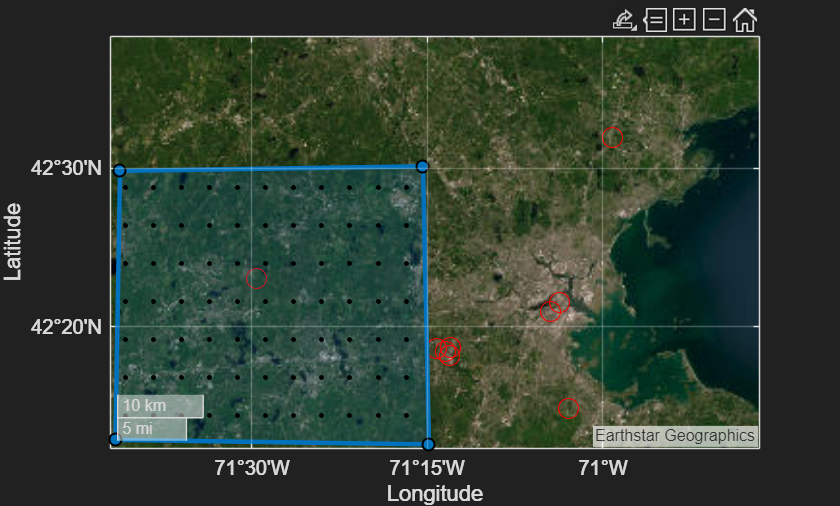

% Geoaxes plot provides satellite view
missionView = geoaxes('Basemap','satellite');
hold(missionView,"on")

% Plot radar locations
geoplot(missionView, rdrlats, rdrlons, 'LineStyle','none','Marker','o', 'MarkerSize', 10, 'Color', 'r');

% Center us over Massachusetts Bay and put us at 60 km above the ground
lla0 = [mean(rdrlats), mean(rdrlons) 0];
missionView.MapCenter = lla0(1:2);
zoomLevel = heightToZoomLevel(60000, 42.354890608305496);
missionView.ZoomLevel = zoomLevel;

% Draw region of interest for coverage
ROI = drawpolygon(missionView); 
ROI.Tag = "Radar Coverage ROI"; 
RadarCoveragePolyshape = polyshape(ROI.Position);

delta = 0.04; % Target spacing in latitude and longitude (degrees) -- effectively our coverage resolution here.
tgtHgtsAGL = 3e3:1e3:8e3; % Target spacing above ground level (meters) -- resolution in altitude of coverage plot.
[tgtLLA,hTgts] = helperRadarCoverageTargetGrid(RadarCoveragePolyshape,delta,tgtHgtsAGL,missionView);

## Set Up Coverage Analysis for Radar

tgtlats = tgtLLA(1, :);
tgtlons = tgtLLA(2, :);
tgtalts = tgtLLA(3, :);

viewer.Name = "Radar Coverage Region of Interest";
regionData = propagationData(tgtlats,tgtlons,'Area',ones(size(tgtlats)));
contour(regionData,'ShowLegend',false,'Colors','green','Levels',0)

## Calculate SNR for Target Positions

% Create a terrain propagation model, using TIREM or Longley-Rice
tiremloc = tiremSetup;
if ~isempty(tiremloc)
    pm = propagationModel('tirem');1
else
    pm = propagationModel('longley-rice');
end

% Compute additional path loss due to terrain and return distances between radars and targets 
[L, ds] = helperPathlossOverTerrain(pm, rdrtxs, rdrrxs, tgtlats, tgtlons, 5);

% Compute SNR for all radars and targets
numtgts = numel(tgtlats);
numrdrs = numel(rdrtxs);
rawsnr = zeros(numtgts,numrdrs);
for tgtind = 1:numtgts
    for rdrind = 1:numrdrs
        rawsnr(tgtind,rdrind) = radareqsnr(lambda,ds(tgtind,rdrind),Ptx,pulsewidth, ...
            'Gain',antgain,'RCS',tgtrcs,'Loss',L(tgtind,rdrind));
    end
end

snr = max(rawsnr,[],2);

% Show selected radar sites using red markers
viewer.Name = "Radar Coverage";
clearMap(viewer)
show(rdrtxs)


% We could update the plot to correspond to probability of detection
% instead of SNR using detectability

% Plot radar coverage
rdrData = propagationData(tgtlats,tgtlons,"SNR",snr);
legendTitle = "SNR" + newline + "(dB)";
contour(rdrData, ...
   "Levels",snrthreshold, ...
   "Colors","green", ...
   "LegendTitle",legendTitle)

## Radar Scenario Analysis

**TODO: **Here are next steps we will need to take in the development of the model

- Add a reasonable tracker that does decent pose estimation of the targets as they move through the scenario

- Update the scanning on the radar systems to match what is expected in reality

- Report the tracks to another siteviewer instance so we can steer the comms arrays and report link budget analysis

- Use the link margin to determine data rates for the comms system throughout the scenario

Let's set up a radar scenario here.  Our objective is first to track the targets, then to feed that data to comms systems to do a link budget analysis.

### Set up the radar

FinalRDGScript; % Script autogenerated (and lightly modified to remove the autogenerated scenario) from the Radar Designer app to set up a RadarDataGenerator statistical radar model

% This is the radar model we'll use that matches the specs above
radarSensorModel

### Set up the radar scenario

scene = radarScenario(IsEarthCentered=true, UpdateRate=0, StopTime=60*60*2); % Run an earth-centered radar scenario with a variable-step solver (to account for sensors operating at potentially different rates) for 2 hrs.

### Add radar platforms to the scenario

for ii = 1:length(rdrlats)
    thisSensor = clone(radarSensorModel);
    thisSensor.SensorIndex = ii;
    radarPlats(ii) = platform(scene, Position = [rdrlats(ii) rdrlons(ii) 500], Orientation = [90 0 0], Sensors=thisSensor); %#ok Want this to look east
end

### Add radar targets (boats?) to the scenario

numTgts = 5;
rng("default")
tgtTrajectories = generateTargetTrajectories(ROI.Position, numTgts, 2, scene.StopTime, lla0);

for ii = 1:numTgts
    tgtSignature = rcsSignature(Pattern=ones(2)*pow2db(tgtrcs), FluctuationModel="Swerling0"); % Can modify the swerling models in here.  Use 'doc rcsSignature' in the command window to see more.
    tgtPlats(ii) = platform(scene, Trajectory=tgtTrajectories{ii}); %#ok
end

### Set up scenario visualization

viewer = trackingGlobeViewer;

### Run and visualize radar scenario while feeding the tracks to siteviewer for comms modeling

while advance(scene)
    plotTrajectory(viewer, tgtTrajectories);
    plotPlatform(viewer, [radarPlat2Struct(radarPlats), radarPlat2Struct(tgtPlats)], "ECEF");
    covCon = coverageConfig(scene);
    plotCoverage(viewer, covCon, "ECEF");
    dets = detect(scene);
    plotDetection(viewer, dets, 'ECEF');

end

## Helper Functions

function platStruct = radarPlat2Struct(radarPlats)
    platStructTemplate.Position = [0, 0, 0];
    platStructTemplate.PlatformID = 0;
    platStructTemplate.Dimensions.Length = 0;
    platStructTemplate.Dimensions.Width = 0;
    platStructTemplate.Dimensions.Height = 0;
    platStructTemplate.Dimensions.OriginaOffset = [0, 0, 0];
    platStructTemplate.Orientation = [0, 0, 0];

    platStruct = repmat(platStructTemplate, [1, length(radarPlats)]);

    for ii = 1:length(radarPlats)
        platStruct(ii).Position = lla2ecef(radarPlats(ii).Position);
        platStruct(ii).PlatformID = radarPlats(ii).PlatformID;
        platStruct(ii).Orientation = [0, 0, 0]; % Since we're looking at points, don't worry about plotting orientation -- even though the scenario considers this
    end
end

function zoomLevel = heightToZoomLevel(height, lat)
    % Takes a specified height (m) and converts this to a zoom level for use
    % with geoplot.
    earthCircumference = 2 * pi * 6378137;
    zoomLevel = log2((earthCircumference *cosd(lat)) / height) + 1;
    zoomLevel = max(0, zoomLevel);
    zoomLevel = min(19, zoomLevel);
end

function targetTrajectories = generateTargetTrajectories(TargetRegion, numTgts, maxVel, scStopTime, lla0)
    startPosition = zeros(numTgts,2);
    stopPosition = zeros(numTgts,2); 
    assigned = zeros(height(startPosition),1,'logical'); 

    if ~isempty(TargetRegion)
        % Get the general polygon region
        latBounds = [min(TargetRegion(:,1)),max(TargetRegion(:,1))];
        lonBounds = [min(TargetRegion(:,2)),max(TargetRegion(:,2))];

        while nnz(~assigned) > 0
            % Generate random points in the bounds
            nRandom = nnz(~assigned); 
            randLats = (latBounds(2)-latBounds(1)).*rand(nRandom,1) + latBounds(1); 
            randLons = (lonBounds(2)-lonBounds(1)).*rand(nRandom,1) + lonBounds(1); 
            
            % test these points for being in the polygon
            validPoints = inpolygon(randLats,randLons,TargetRegion(:,1),TargetRegion(:,2));
    
            % write valid points to the polygon
            if nnz(validPoints)>0
                writeIdx = find(~assigned,nnz(validPoints));
                startPosition(writeIdx,:) = [randLats(validPoints),randLons(validPoints)];

                % Determine end position based on velocity up to maxVel
                % argument.  We'll make a simplifying flat earth assumption
                % here to calculate the distance traveled in a straight
                % line during the scenario

                headingRelToNorth = 360 * rand(nnz(validPoints), 1);
                randVel = maxVel * rand(nnz(validPoints), 1);
                NEDPositions = lla2ned([randLats(validPoints) randLons(validPoints) zeros(nnz(validPoints), 1)], lla0, "flat");
                NEDPositions(:, 3) = 0;
                [finalX, finalY, finalZ] = sph2cart(headingRelToNorth, zeros(size(randVel)), randVel*scStopTime);
                finalLLAs = ned2lla(NEDPositions + [finalX, finalY, finalZ], lla0, "flat");
                stopPosition(writeIdx, :) = finalLLAs(:, 1:2);

                assigned(writeIdx) = true;
            end
        end

        startPosition = [startPosition, zeros(numTgts, 1)];
        stopPosition = [stopPosition, zeros(numTgts, 1)];
        
        targetTrajectories = cell(1, numTgts);

        for ii = 1:numTgts
            targetTrajectories{ii} = geoTrajectory([startPosition(ii, :); stopPosition(ii, :)], [0, scStopTime]);
        end
    else
        warning('Please input a mission region.')
    end
end

**parseTxtRadarLocs**

function [rdrlats, rdrlons,rdrcoverage,rdrheights] = parseTxtRadarLocs(filename)

% Read the file
fid = fopen(filename, 'r');
lines = textscan(fid, '%s', 'Delimiter', '\n');
fclose(fid);
lines = lines{1};

% Initialize arrays
rdrlats = [];
rdrlons = [];
rdrcoverage = [];
rdrheights = [];


% Loop through lines and 
for i = 1:length(lines)
    line = lines{i};

    % Extract LatLon values
    if contains(line, 'LatLon:')
        % Extract the part after 'LatLon:'
        tokens = regexp(line, 'LatLon:\s*([-\d\.]+),\s*([-\d\.]+)', 'tokens');
        if ~isempty(tokens)
            lat = str2double(tokens{1}{1});
            lon = str2double(tokens{1}{2});
            rdrlats(end+1) = lat; %#ok<AGROW>
            rdrlons(end+1) = lon; %#ok<AGROW>
        end
    end


    % Extract Coverage
    if contains(line, 'Coverage:')
        tokens = regexp(line, 'Coverage:\s*([\d\.]+)\s*mile', 'tokens');
        if ~isempty(tokens)
            coverage = str2double(tokens{1}{1});
            rdrcoverage(end+1) = coverage; %#ok<AGROW>
        end
    end

    % Extract Tower Height (AGL)
    if contains(line, 'ALT:')
        tokens = regexp(line, 'ALT:\s*(\d+)\''\s*AGL', 'tokens');
        if ~isempty(tokens)
            height = str2double(tokens{1}{1});
            height = convlength(height,'ft','m');
            rdrheights(end+1) = height; %#ok<AGROW>
        end
    end


end

end